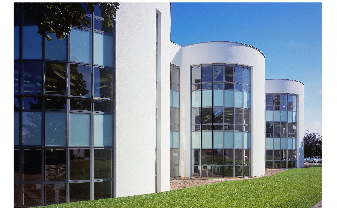

clc;
clear;
cd /Users/lumizhang/Documents/GitHub/AI_B_Project_2023/
target = imread("dataset/mosaic_target2.jpg");
imshow(target)

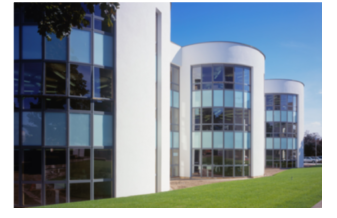

target = imgaussfilt(target,5);
imshow(target);

tiles = {};

% Read the Natural images to tiles
names = cell2mat(splitlines(fileread("dataset/natural_training.txt")));
names = strcat("dataset/", names);
fit_num = numel(names);
for i = 1:numel(names)
    name = names(i, :);
    source = imread(name);
    r = mean(source(:,:,1),'all');
    g = mean(source(:,:,2),'all');
    b = mean(source(:,:,3),'all');
    tiles{i,1} = name;
    tiles{i,2} = r;
    tiles{i,3} = g;
    tiles{i,4} = b;
end

% Read the Manmade images to tiles
names = cell2mat(splitlines(fileread("dataset/manmade_training.txt")));
names = strcat("dataset/", names);
for i = 1:numel(names)
    name = names(i, :);
    source = rgb2hsv(imread(name));
    h = mean(source(:,:,1),'all');
    s = mean(source(:,:,2),'all');
    b = mean(source(:,:,3),'all');
    tiles{i + fit_num,1} = name;
    tiles{i + fit_num,2} = r;
    tiles{i + fit_num,3} = g;
    tiles{i + fit_num,4} = b;
end

num_x_tiles = 100;
num_y_tiles = 100;
target_size = size(target);
x_width = floor(target_size(2) / num_x_tiles) + 1;
y_width = floor(target_size(1) / num_y_tiles) + 1;

Testing the resizing of the image

%target_resized = imresize(target, [y_width x_width]);
%imshow(target_resized)

And it worked well

source_cell = {};
alpha = 0.33;
beta = 0.33;
for i = 1:num_x_tiles
    for j = 1:num_y_tiles
        x_start = (i - 1) * x_width + 1;
        x_end = i * x_width;
        y_start = (j - 1) * y_width + 1;
        y_end = j * y_width;
        if x_end > target_size(2)
            x_end = target_size(2);
        end
        if y_end > target_size(1)
            y_end = target_size(1);
        end
        mat = target(y_start:y_end, x_start:x_end, :);
        mat_r = mean(mat(:,:,1), 'all');
        mat_g = mean(mat(:,:,2), 'all');
        mat_b = mean(mat(:,:,3), 'all');

        fit = inf;
        for k = 1:1000
            r_dif = abs(mat_r - tiles{k, 2});
            g_dif = abs(mat_g - tiles{k, 3});
            b_dif = abs(mat_b - tiles{k, 4});

            score = alpha * r_dif + beta * g_dif + (1 - alpha - beta) * b_dif;
            if score < fit
                fit = score;
                source_cell{j,i} = tiles{k, 1};
            end
        end
    end
end

mosaic_size = size(source_cell);
images = {};

for i = 1:mosaic_size(2)
    for j = 1:mosaic_size(1)
        images{j, i} = imresize(imread(source_cell{j,i}), [y_width x_width]);
    end
end

rowImage = cell(mosaic_size(1),1);
for i = 1:mosaic_size(1)
    rowImage{i} = horzcat(images{i,:});
end

mosaic = vertcat(rowImage{:});

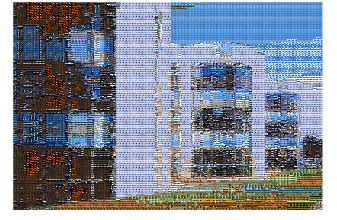

imshow(mosaic)